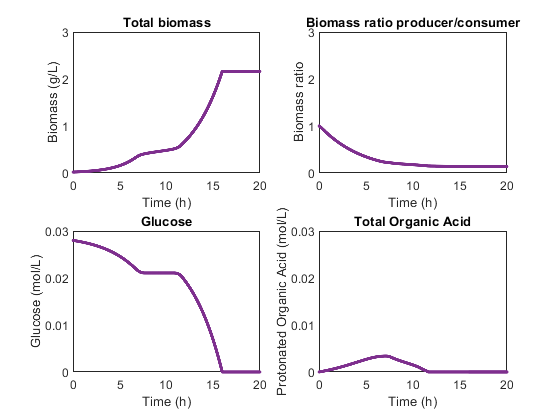

% Script and function to model acetate consortium dynamics in buffer-limited batch culture
% A. Beck, R. Carlson, and T. Gedeon
% May 2022 (initial development)

clear all
clc

% Define time length and initial conditions, set options, and solve
tspan = [0,... % (h) start time
   35]; % (h) end time
y0 = [0.010000,... % (g/L) initial producer biomass concentration
    0.010000,... % (g/L) initial scavenger biomass concentration
    0.028000,... % (mols/L) initial glucose concentration
    0.00000,... % (mols/L) initial acetate concentration
    10^-7]; % (mols/L) initial proton concentration

options=odeset('AbsTol',1e-12,... % threshold below which value of solution becomes unimportant
      'RelTol',1e-12,... % controls # of correct digits in all solution components except those < than AbsTol
      'MaxStep',1e-1); % upper bound on size of any step taken by the solver
%      'OutputFcn','odeplot'); % plots solution components as they are computed
[t,y]=ode45(@fun_acecom,tspan,y0,options); % solve ODEs in fun_acecom function below


tau=20;% set time scale for figures

pK1=3.86; %lactic acid

% Compare biomass concentrations between model and experiment
%figure
subplot(2,2,1)
%plot(t,y(:,1)+y(:,2),'.','color',[0.4667 0.6745 0.1882])% green
%plot(t,y(:,1)+y(:,2),'.','color',[0.8500 0.3250 0.0980]) % orange
plot(t,y(:,1)+y(:,2),'.','color',[0.4940 0.1840 0.5560]) % purple
hold on
title('Total biomass')
xlabel('Time (h)')
ylabel('Biomass (g/L)')
axis([0 tau 0 3])

%Producer/scavenger biomass ratio
subplot(2,2,2)
%plot(t,y(:,1)./y(:,2),'.','color',[0.4667 0.6745 0.1882])% green
%plot(t,y(:,1)./y(:,2),'.','color',[0.8500 0.3250 0.0980]) % orange
plot(t,y(:,1)./y(:,2),'.','color',[0.4940 0.1840 0.5560]) % purple
hold on
%plot(t,y(:,2),'.','color',[0.4940 0.1840 0.5560])% purple
title('Biomass ratio producer/consumer')
xlabel('Time (h)')
ylabel('Biomass ratio')
axis([0 tau 0 3])

% Compare glucose concentrations between model and experiment
subplot(2,2,3)
%plot(t,y(:,3),'.','color',[0.4667 0.6745 0.1882])% green
%plot(t,y(:,3),'.','color',[0.8500 0.3250 0.0980]) % orange
plot(t,y(:,3),'.','color',[0.4940 0.1840 0.5560]) % purple
hold on
plot(t,1.44,'-b')
title('Glucose')
xlabel('Time (h)')
ylabel('Glucose (mol/L)')
axis([0 tau 0 0.03])


% protonated or total acetate
subplot(2,2,4)
%Protonated organic acid
%plot(t,y(:,4)./(1+10.^(-log10(y(:,5))-pK1)),'.','color',[0.4667 0.6745 0.1882])% green
%plot(t,y(:,4)./(1+10.^(-log10(y(:,5))-pK1)),'.','color',[0.8500 0.3250 0.0980]) % orange
%plot(t,y(:,4)./(1+10.^(-log10(y(:,5))-pK1)),'.','color',[0.4940 0.1840 0.5560]) % purple
%Total organic acid
%plot(t,y(:,4)),'.','color',[0.4667 0.6745 0.1882])% green
%plot(t,y(:,4)),'.','color',[0.8500 0.3250 0.0980]) % orange
plot(t,y(:,4),'.','color',[0.4940 0.1840 0.5560]) % purple
hold on
title('Total Organic Acid')
xlabel('Time (h)')
ylabel('Protonated Organic Acid (mol/L)')
axis([0 tau 0 0.03])




% THE END



function dydt = fun_acecom(t,y)

YXGp = 0.05; % (g/g) yield of producer biomass per glucose 
YXAs = 0.5; % (g/g) (g/g) yield of consumer biomass per lactate
YAXp = 15; % (g/g) yield of lactate per producer biomass


%new parameter values for protonated acetate
P0= 0.0063; %M 0.0063 (low buffer) 0.064 M (normal buffer)
YH =0.009;% mol H+/g cdw 
C=10^(-3.86); %lactic acid
D=10^(-7.03);


% Define ODEs
xp = y(1,1); % biomass of the producer
xs = y(2,1); % biomass of the consumer
G = y(3,1);  % glucose
A = y(4,1); % lactic acid total
H = y(5,1); % H+

f1star= (1/H)*C;

## Equations for growth rates

mumaxp=0.28; %1/h maximum growth rate of the producer  
muA = 0.50; %1/h maximum growth rate of the consumer  
KG= 0.005;% M  half-saturation constant for glucose substrate

%Producer growth rate

Astar=0.45;% mM
mup = mumaxp*(1000*G/(KG+1000*G))*max([0 (1-((1000*A)/Astar)*1/(1+f1star))]);

% Consumer growth rate

%Aiba A4
KAA=0.0038;%mM  
KI= 0.317;%mM  
mus = muA*(1000*A)/(KAA+1000*A)*exp(-(1/KI)*1000*A*(1/(1+f1star)));% protonated only


% ODEs


dydt(1,1) = mup*xp; % ODE for producer biomass concentration
dydt(2,1) = mus*xs; % ODE for scavenger biomass concentration
dydt(3,1) = -(1/YXGp)*mup*xp*(1/180); % ODE for glucose concentration
dydt(4,1) = (YAXp*mup*xp*(1/90)-(1/YXAs)*mus*xs*(1/90)); % ODE for lactic acid (MW = 90) 
dydt(5,1) =(mup*xp+mus*xs)*YH/(1+(D*P0)/(D+H)^2 + (C*A)/(C+H)^2); %proton balance with buffers


end